# 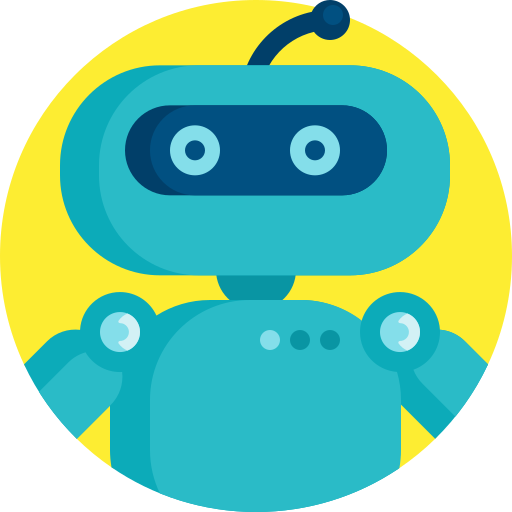

# **MEC4127F: Introduction to Robotics**

# Project — Part 1

## Project brief

You are tasked with designing an explicit complementary filter for use on a quadcopter to determine the platform's orientation, based on the theory covered in **Chapter 4**. The available sensors available include a three-axis gyroscope, accelerometer, and magnetometer. The accelerometer has a constant, non-zero bias term, whereas the gyroscope bias is possibly time-varying and must be estimated as part of the explicit complementary filter. The magnetometer measurement has no bias. You can assume that the quadcopter does not experience any translational acceleration. 

The quadcopter is initialised such that ${^W{\bf q}_B}=[1~~0~~0~~0]^T$ at $t=0$ seconds. After two seconds, the quadcopter experiences rotational motion. The explicit complementary filter must be designed such that the orientation estimate converges on the true behaviour within $5$ seconds of start-up.

You are provided with the accompanying simulink file, **Project_Part1.slx**, where you will construct and test your explicit complementary filter. The complementary filter must be implemented solely using Simulink blocks — user-defined MATLAB functions are not permitted. A subsystem within the explicit complementary filer subsystem has been provided and accounts for the integration and exponential mapping from the estimated angular velocity to the quaternion estimate.

When the simulation is run, data is outputted to the MATLAB workspace using the `out.simout` time-series variable (see below). The code blocks below should be used to facilitate the image generation of your project "report". Note that the data available here will also assist with constructing your filter.

The questions can be found in the Amathuba **Project — Part 1** quiz.

You will require the following toolboxes for the simulation:

- Sensor Fusion and Tracking Toolbox,

- DSP System Toolbox,

- UAV Toolbox — optional and only if you want to visualise the 3D quadcopter in Simulink.

Toolboxes can be installed retroactively by going to *APPS* in MATLAB, followed by *Get More Apps*, clear the filter and then search for the name of the toolbox. Lastly, click install, which may prompt a restart from MATLAB, depending on the toolbox.

## Logged data

The **Project_Part1.slx** simulation must be run before this information is available in the `MATLAB` workspace. Note that after closing and reopening `MATLAB`, the workspace is cleared.

t = out.simout.q_act.time; %time array
q = out.simout.q_act.data; %true quaternion
q_ = out.simout.q_est.data; %estimated quaternion

b_ = out.simout.bg_est.data; %estimated gyroscope bias
b = out.simout.bg_act.data; %true gyroscope bias

gyro_meas = out.simout.gyro_meas.data; %gyroscope measurement
accel_meas = out.simout.signal6.data; %accelerometer measurement
mag_meas = out.simout.mag_meas.data; %magnetometer measurement

## IMU measurements

#### Gyroscope measurement

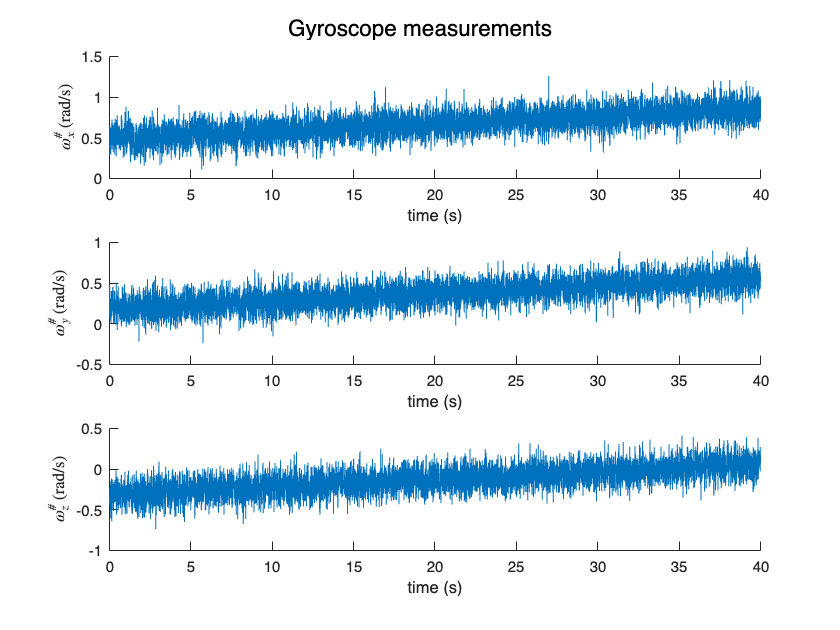

figure(2),clf,sgtitle('Gyroscope measurements')
subplot(3,1,1),hold on
plot(t,gyro_meas(1,:)),xlabel('time (s)'),ylabel('$\omega^\#_x$ (rad/s)',Interpreter='latex')
subplot(3,1,2),hold on
plot(t,gyro_meas(2,:)),xlabel('time (s)'),ylabel('$\omega^\#_y$ (rad/s)',Interpreter='latex')
subplot(3,1,3),hold on
plot(t,gyro_meas(3,:)),xlabel('time (s)'),ylabel('$\omega^\#_z$ (rad/s)',Interpreter='latex')

#### Accelerometer measurement

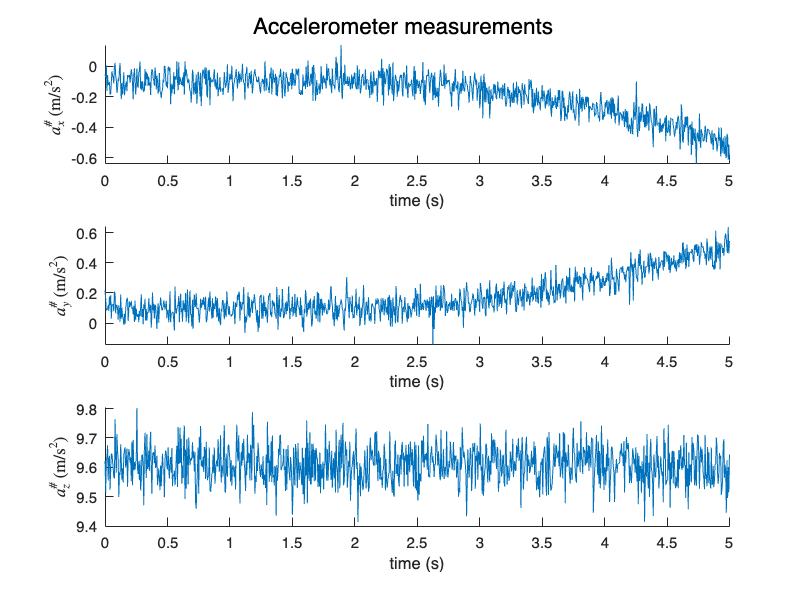

figure(2),clf,sgtitle('Accelerometer measurements')
subplot(3,1,1),hold on
plot(t,accel_meas(1,:)),xlabel('time (s)'),ylabel('$a^\#_x$ (m/s$^2$)',Interpreter='latex')
subplot(3,1,2),hold on
plot(t,accel_meas(2,:)),xlabel('time (s)'),ylabel('$a^\#_y$ (m/s$^2$)',Interpreter='latex')
subplot(3,1,3),hold on
plot(t,accel_meas(3,:)),xlabel('time (s)'),ylabel('$a^\#_z$ (m/s$^2$)',Interpreter='latex')

#### Magnetometer measurement

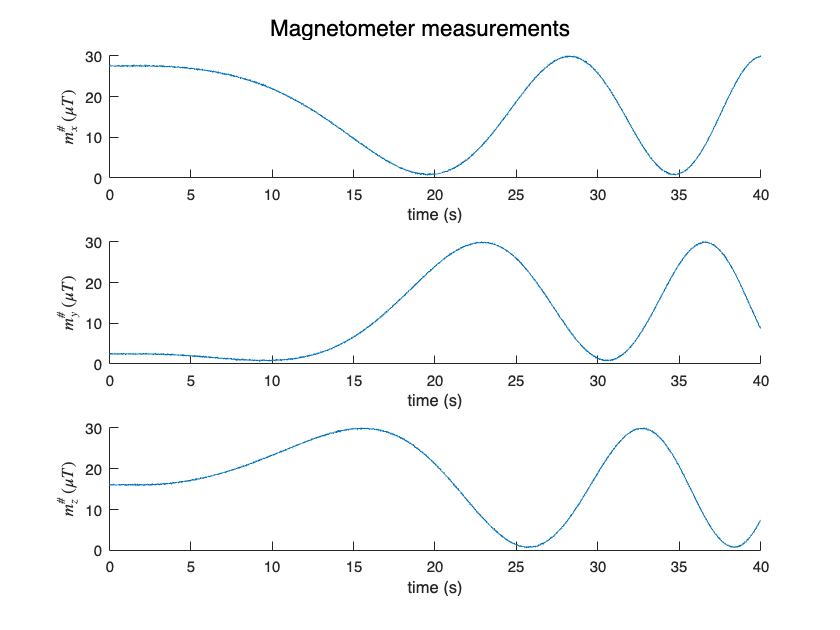

figure(2),clf,sgtitle('Magnetometer measurements')
subplot(3,1,1),hold on
plot(t,mag_meas(1,:)),xlabel('time (s)'),ylabel('$m^\#_x$ ($\mu T$)',Interpreter='latex')
subplot(3,1,2),hold on
plot(t,mag_meas(2,:)),xlabel('time (s)'),ylabel('$m^\#_y$ ($\mu T$)',Interpreter='latex')
subplot(3,1,3),hold on
plot(t,mag_meas(3,:)),xlabel('time (s)'),ylabel('$m^\#_z$ ($\mu T$)',Interpreter='latex')

## State estimates vs actual

#### Quaternion estimate vs actual

Ensure that the `q_est` output port within the Simulink ECF subsystem is connected to the quaternion estimate from your filter.

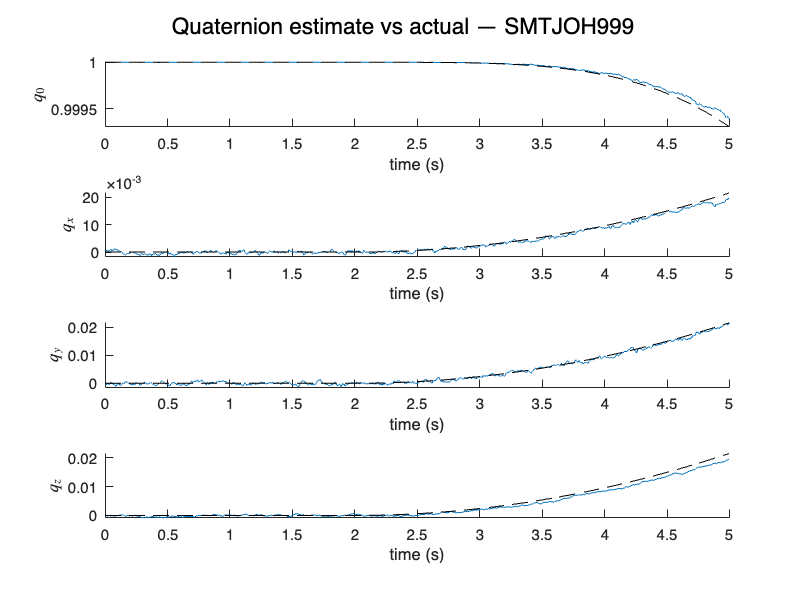

figure(1),clf,sgtitle('Quaternion estimate vs actual — SMTJOH999')
subplot(4,1,1),hold on
plot(t,q_(:,1)),plot(t,q(1,:),'--k'),xlabel('time (s)'),ylabel('$q_0$',Interpreter='latex')
subplot(4,1,2),hold on
plot(t,q_(:,2)),plot(t,q(2,:),'--k'),xlabel('time (s)'),ylabel('$q_x$',Interpreter='latex')
subplot(4,1,3),hold on
plot(t,q_(:,3)),plot(t,q(3,:),'--k'),xlabel('time (s)'),ylabel('$q_y$',Interpreter='latex')
subplot(4,1,4),hold on
plot(t,q_(:,4)),plot(t,q(4,:),'--k'),xlabel('time (s)'),ylabel('$q_z$',Interpreter='latex')

% legend

#### Gyroscope bias estimate vs actual

Ensure that the bg`_est` output port within the Simulink ECF subsystem is connected to the gyroscope bias estimate from your filter.

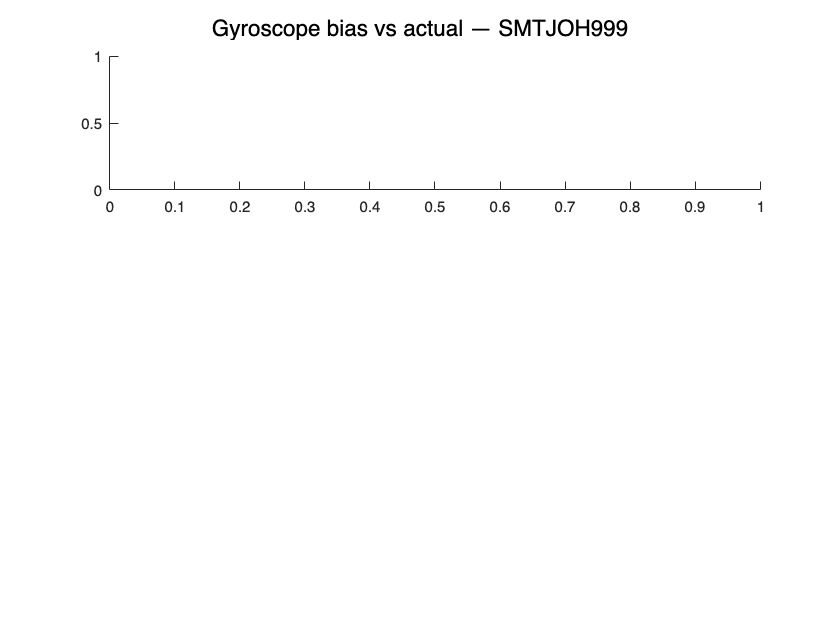

figure(2),clf,sgtitle('Gyroscope bias vs actual — SMTJOH999')
subplot(3,1,1),hold on

plot(t,b_(1,:)),plot([t(1) t(end)],[b(1) b(1)],'--k'),xlabel('time (s)'),ylabel('$b_x$',Interpreter='latex')

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

subplot(3,1,2),hold on
plot(t,b_(2,:)),plot([t(1) t(end)],[b(2) b(2)],'--k'),xlabel('time (s)'),ylabel('$b_y$',Interpreter='latex')
subplot(3,1,3),hold on
plot(t,b_(3,:)),plot([t(1) t(end)],[b(3) b(3)],'--k'),xlabel('time (s)'),ylabel('$b_z$',Interpreter='latex')